% Datos del GP2Y0A21 (distancia vs. voltaje)
d_21 = [5, 10, 15, 20, 25, 30, 35, 40, 45, 50, 55, 60, 65, 70]; % cm
V_21 = [3.2, 2.35, 1.6, 1.29, 1.18, 1.0, 0.87, 0.75, 0.71, 0.65, 0.63, 0.57, 0.5, 0.5]; % V

% Datos del GP2Y0A41 (distancia vs. voltaje)
d_41 = [5, 10, 15, 20, 25, 30, 35, 40, 45, 50, 55, 60, 65]; % cm
V_41 = [3.27, 2.45, 1.82, 1.56, 1.38, 1.27, 1.07, 0.97, 0.88, 0.85, 0.81, 0.74, 0.71]; % V

% Ajuste para GP2Y0A21
modelo = fittype('a/(x + b) + c', 'independent', 'x', 'dependent', 'y');
opts = fitoptions('Method', 'NonlinearLeastSquares');
opts.StartPoint = [1, 1, 0]; % Valores iniciales para a, b, c

[fit_21, gof_21] = fit(d_21', V_21', modelo, opts);
disp('Ecuación para GP2Y0A21:');

Ecuación para GP2Y0A21:


disp(fit_21);

     General model:
     fit_21(x) = a/(x + b) + c
     Coefficients (with 95% confidence bounds):
       a =       34.19  (27.6, 40.78)
       b =       5.689  (3.807, 7.572)
       c =     0.03367  (-0.08971, 0.1571)



% Ajuste para GP2Y0A41
[fit_41, gof_41] = fit(d_41', V_41', modelo, opts);
disp('Ecuación para GP2Y0A41:');

Ecuación para GP2Y0A41:


disp(fit_41);

     General model:
     fit_41(x) = a/(x + b) + c
     Coefficients (with 95% confidence bounds):
       a =       38.48  (32.45, 44.5)
       b =       7.386  (5.67, 9.103)
       c =      0.1751  (0.06884, 0.2813)


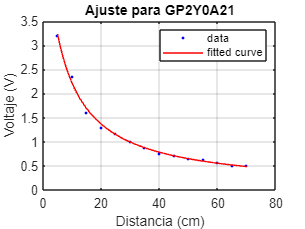


% Gráfica para GP2Y0A21
figure;
plot(fit_21, d_21, V_21);
xlabel('Distancia (cm)');
ylabel('Voltaje (V)');
title('Ajuste para GP2Y0A21');
grid on;

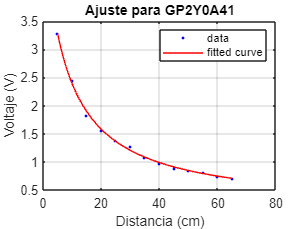


% Gráfica para GP2Y0A41
figure;
plot(fit_41, d_41, V_41);
xlabel('Distancia (cm)');
ylabel('Voltaje (V)');
title('Ajuste para GP2Y0A41');
grid on;


% Función para calcular distancia a partir del voltaje (GP2Y0A21)
a_21 = fit_21.a;
b_21 = fit_21.b;
c_21 = fit_21.c;

d_calculada_21 = @(V) (a_21 ./ (V - c_21)) - b_21;

% Ejemplo: Calcular distancia para V = 1.5V
V_ejemplo = 1.5;
disp(['Para V = ', num2str(V_ejemplo), 'V, d = ', num2str(d_calculada_21(V_ejemplo)), ' cm']);

Para V = 1.5V, d = 17.6261 cm
